## The purpose of this tutorial is to demonstrate the intermediate transfer functions composing the AWG.

clear; clc;

Create AWG definition for a 100GHz demultiplexer on SOI

def = awg.AWG({
    'lambda_c', 1.550       % design center wavelength
    'clad',     'SiO2'      % top cladding material
    'core',     'Si'        % core (guiding) material
    'subs',     'SiO2'      % bottom cladding material
    'w',        0.450       % waveguide core width
    'h',        0.220       % waveguide core height (thickness)
    't',        0           % waveguide slab thickness (if using rib wg)
    'N',        40          % number of arrayed waveguides
    'No',       8           % number of output channels
    'm',        75          % diffraction order
    'R',        130         % focal length (radius)
    'L0',       20          % mininum array waveguide length
    'd',        2.5         % array aperture spacing (center-to-center)
    'do',       1.8         % output aperture spacing
    'wi',       1.5         % input aperture width
    'wg',       1.8         % array aperture width
    'wo',       1.5         % output aperture width
});

Generate input field distribution

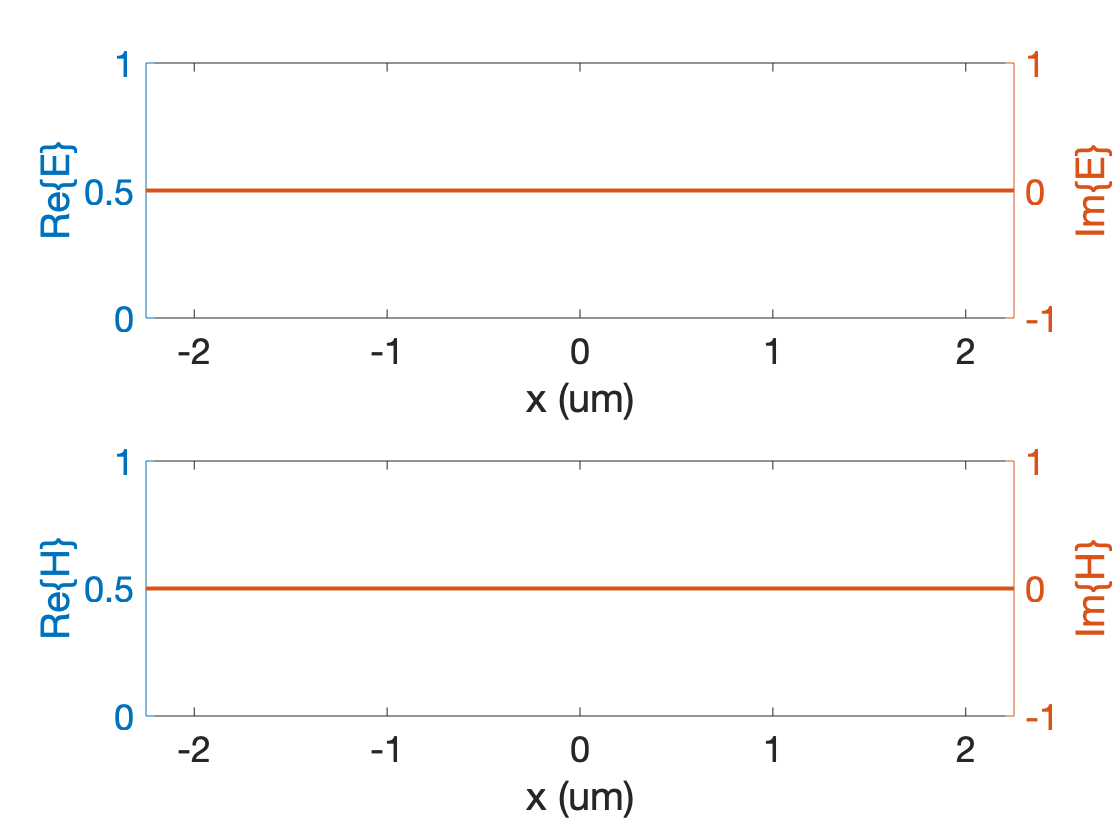

F1 = awg.iw(def, 1.5473, 0, 'solve', 'Points', 100);

awg.plotfield(F1);

Propagate input field accross free propagation region

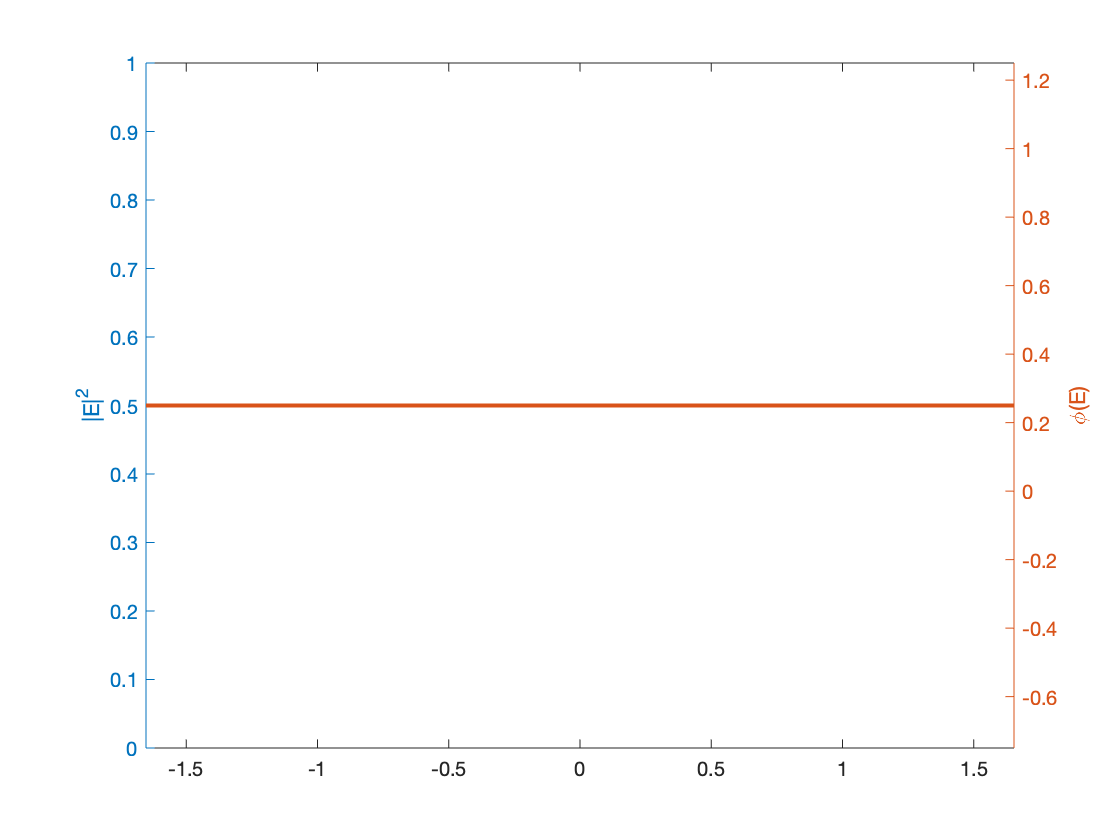

Error using ylim (line 31)
Limits must be a 2-element vector of increasing numeric values.

Error in awg.plotfield/plotField1D (line 208)
            ylim([miny,maxy])

Error in awg.plotfield (<

F2 = awg.fpr1(def, 1.5473, F1, 'Points', 500);

awg.plotfield(F2, 'PlotPhase', 1, 'UnwrapPhase', 1, 'NormalizePhase', 1);

Couple diffracted field to array apertures and propagate modes

F3 = awg.aw(def, 1.5473, F2, 'solve');
awg.plotfield(F3, 'PlotPhase', 1, 'UnwrapPhase', 1, 'NormalizePhase', 1);


Propagate array field accross free propagation region

F4 = awg.fpr2(def, 1.5473, F3, 'Points', 500);
awg.plotfield(F4, 'PlotPhase', 1, 'UnwrapPhase', 1, 'NormalizePhase', 1);


Couple diffracted field to output apertures

T = awg.ow(def, 1.5473, F4, 'solve');

figure
bar(T);
xlabel('Output #')
ylabel('Transmission')
set(gca,'FontSize',18)